## Add noise to the MRI image

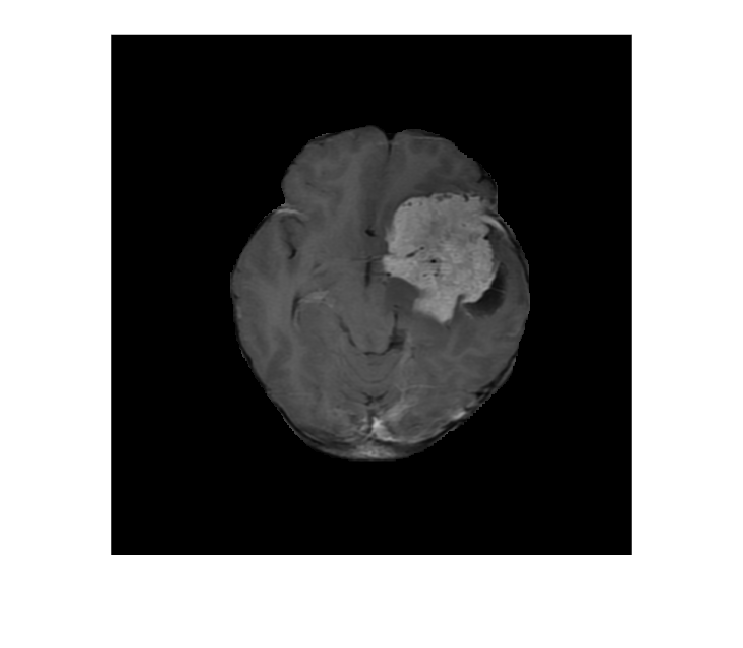

%or = imread('..\brain\data\12 Anh Tach Hop So\U Mang Nao (Meningioma Tumor)\Tumor3_Skull_Tripped.jpg');
or = imread("Tumor3_Skull_Tripped.png");
figure;
imshow(or);

noise_img = uint8(imnoiseFB(or,'gaussian',0.02));

Noises added here is Rican, which is the magnitude of the real and complex value of the Gaussian noise

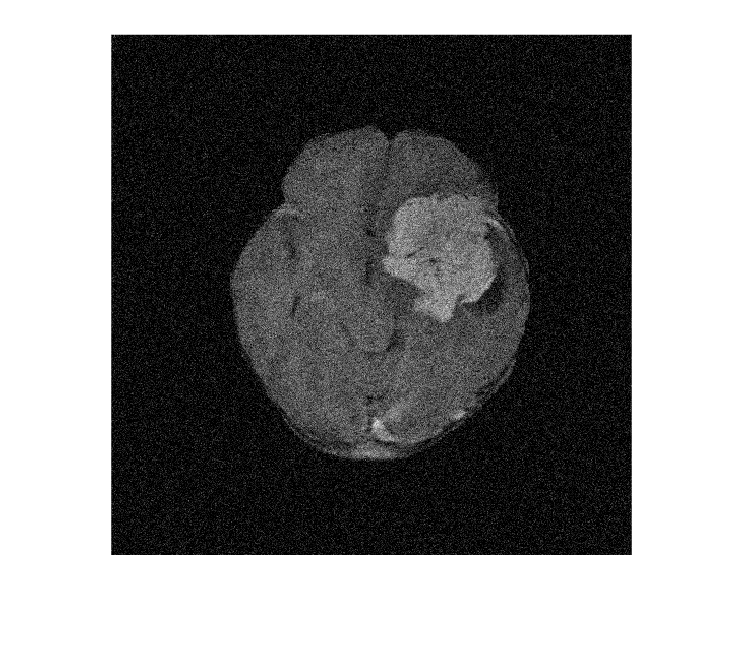

figure;
imshow(noise_img);

[psnr1, snr1] = psnr(noise_img, or);
psnr1

psnr1 = 21.0787

## Choose discrete wavelet type

wmethod = "haar";
level = 4;
fprintf('Decompose using %s wavelet transform \nLevel of decomposition selected is L=%d',wmethod,level);

Decompose using haar wavelet transform 
Level of decomposition selected is L=4

Decompose the noisy image using forward discrete <wmethod> wavelet transform

Level of decomposition selected is L=<level>

[C,S]=wavedec2(noise_img,level,wmethod);

Threshold the horizontal, vertical and diagonal coefficients using soft thresholding separately. 

threshMethod = "heursure";
threshType = "s";
isfilter = true;

aci = S(1,1)*S(1,2); % approximation index
% Baye_coff = C;
Baye_coff = [C(1:aci-1),zeros(1,length(aci:1:length(C)))];
% Function for threshold
threshFunc = getThresh(threshMethod);
% Apply BayesShrink thresholding to detail coefficients at each level
max_level  = length(S)-2;
for level = 1:max_level
    [H, V, D] = detcoef2('all', C, S, level);
     % Apply thresholding
    H = applyFilter(H,threshType,threshFunc);
    V = applyFilter(V,threshType,threshFunc);
    D = applyFilter(D,threshType,threshFunc);
    Baye_coff = replace_detail_coeffs(Baye_coff,S,H,V,D,level);
end

Recontruct

haar_img_1 = uint8(waverec2(Baye_coff,S,wmethod));
figure;
imshow(mat2gray(haar_img_1))

[psnr2_1, snr2_1] = psnr(haar_img_1, or);
psnr2_1

psnr2_1 = 21.1333

### Ulti Funstions

functions for threshold, edge

function f = getThresh(type)
    f=struct;
    % init
    f.threshold = @(C) 0;
    f.estimate_sigma = 0;
    f.getEstimate = @(C) 0;
    switch (type)
        case "bayer" %BayerShrink
            f.getEstimate = @(C) median(abs(C(:))) / 0.6745;
            f.threshold = @(C) f.estimate_sigma / sqrt(max(var(C(:)) - f.estimate_sigma, 0));
        case "visuShrink"
            f.getEstimate = @(C) median(abs(C(:))) / 0.6745;
            f.threshold = @(C) f.estimate_sigma*sqrt(2*log(numel(C(:))));
        case "rigrsure"
            f.threshold = @(C) thselect(C,type);
        case "sqtwolog"
            f.threshold = @(C) thselect(C,type);
        case "heursure"
            f.threshold = @(C) thselect(C,type);
        case "minimaxi"
            f.threshold = @(C) thselect(C,type);
        otherwise
            warning('Unexpected thresh type.')
    end
end

% Apply threshold filter 
function C_n = applyFilter(C,tType,f)
    f.getEstimate(C);
    C_n = wthresh(C,tType,f.threshold(C));
end

% Replace wavelet detail coefficient 
function new_coeffs = replace_detail_coeffs(coeffs, S, H, V, D, level)
    % Get the index ranges for the detail coefficients at the specified level
    pow2 = prod(S(1:end-level, :), 2);
    start_idx = pow2(1)+sum(pow2(2:end-1))*3 + 1;
    H_idx = start_idx : start_idx + pow2(end) - 1;
    start_idx = H_idx(end) + 1;
    V_idx = start_idx : start_idx + pow2(end) - 1;
    start_idx = V_idx(end) + 1;
    D_idx = start_idx : start_idx + pow2(end) - 1;
    
    % Replace the coefficients in the original array
    new_coeffs = coeffs;
    new_coeffs(H_idx) = H(:);
    new_coeffs(V_idx) = V(:);
    new_coeffs(D_idx) = D(:);
end